Load data

china=preprocess('data/china.csv');
korea=preprocess('data/korea.csv');
taiwan=preprocess('data/taiwan.csv');

Rsiduals visualization      

%======CHINA=====
[tr,y_tr,te,y_te] = train_test_split(china);
[beta,stat] = ols(tr,y_tr);

stats = struct with no fields.


stats = struct with fields:
    sigma2: 357.0880

stats = struct with fields:
        sigma2: 357.0880
    sample_var: [18×18 double]

stats = struct with fields:
        sigma2: 357.0880
    sample_var: [18×18 double]
     std_error: [18×1 double]

stats = struct with fields:
        sigma2: 357.0880
    sample_var: [18×18 double]
     std_error: [18×1 double]
           AIC: 6.1801

stats = struct with fields:
        sigma2: 357.0880
    sample_var: [18×18 double]
     std_error: [18×1 double]
           AIC: 6.1801
           BIC: 6.9401

stats = struct with fields:
        sigma2: 357.0880
    sample_var: [18×18 double]
     std_error: [18×1 double]
           AIC: 6.1801
           BIC: 6.9401
            R2: 0.9991

stats = struct with fields:
        sigma2: 357.0880
    sample_var: [18×18 double]
     std_error: [18×1 double]
           AIC: 6.1801
           BIC: 6.9401
            R2: 0.9991
        adj_R2: 0.9985

stats = struct with fields:
        sigma2: 357.0880
    sample_var: [18×18 double]
     std_error: [18×1 double]
           AIC: 6.1801
           BIC: 6.9401
            R2: 0.9991
        adj_R2: 0.9985
            SE: [18×1 double]
     residuals: [40×1 double]

[result] = test_model(beta,tr,y_tr);

result = struct with no fields.


result = struct with fields:
    residuals: [10×1 double]
          SSE: 4.5670e+06
          SST: 3.8864e+06

result = struct with fields:
    residuals: [10×1 double]
          SSE: 4.5670e+06
          SST: 3.8864e+06
           R2: -0.1751

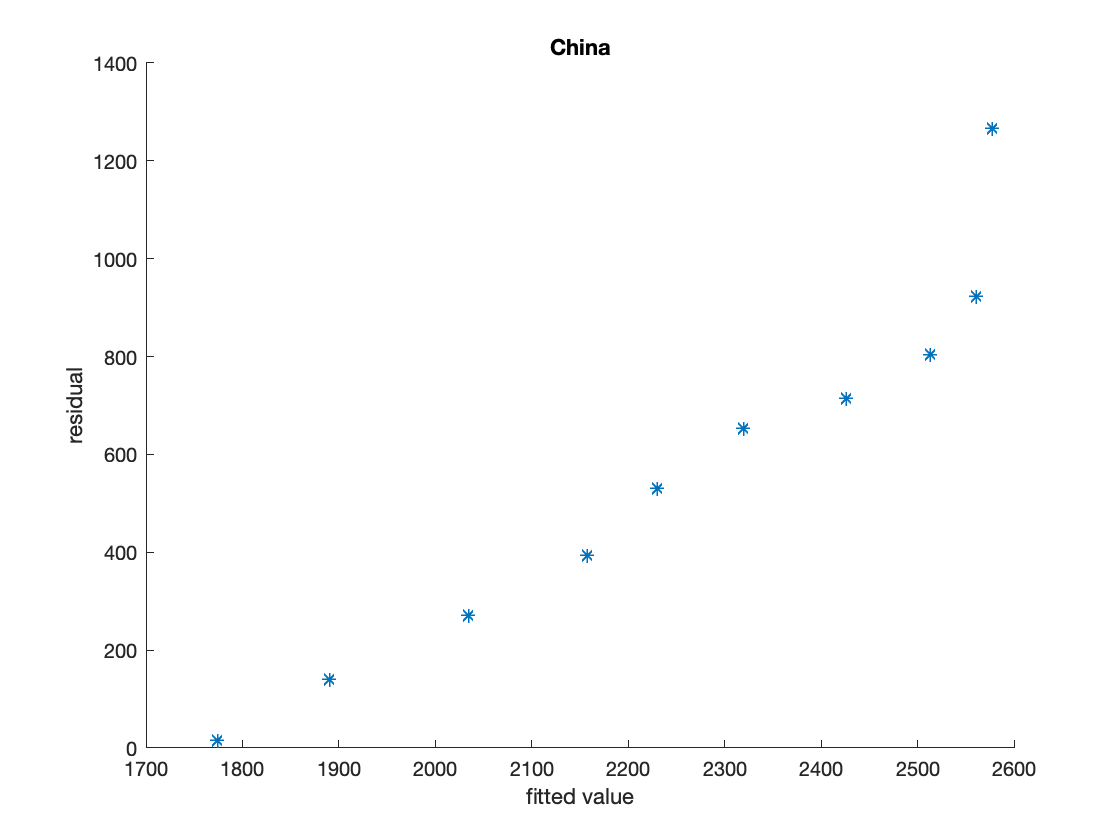

x = 1:1:size(tr);
scatter(result.y_hat,result.residuals,'*');
ylabel('residual') ;
xlabel('fitted value') ;
title('China');

% normalise and select subfeatures
select = [true,false,true,false,true,false,true,true,true,true,false,true,false,false,true,false,false,false];
[tr,te]=standardize(tr(:,select),te(:,select));
[beta,stat2] = ols(tr,y_tr);

stats = struct with no fields.


stats = struct with fields:
    sigma2: 3.8547e+03

stats = struct with fields:
        sigma2: 3.8547e+03
    sample_var: [9×9 double]

stats = struct with fields:
        sigma2: 3.8547e+03
    sample_var: [9×9 double]
     std_error: [9×1 double]

stats = struct with fields:
        sigma2: 3.8547e+03
    sample_var: [9×9 double]
     std_error: [9×1 double]
           AIC: 8.4522

stats = struct with fields:
        sigma2: 3.8547e+03
    sample_var: [9×9 double]
     std_error: [9×1 double]
           AIC: 8.4522
           BIC: 8.8322

stats = struct with fields:
        sigma2: 3.8547e+03
    sample_var: [9×9 double]
     std_error: [9×1 double]
           AIC: 8.4522
           BIC: 8.8322
            R2: 0.9869

stats = struct with fields:
        sigma2: 3.8547e+03
    sample_var: [9×9 double]
     std_error: [9×1 double]
           AIC: 8.4522
           BIC: 8.8322
            R2: 0.9869
        adj_R2: 0.9835

stats = struct with fields:
        sigma2: 3.8547e+03
    sample_var: [9×9 double]
     std_error: [9×1 double]
           AIC: 8.4522
           BIC: 8.8322
            R2: 0.9869
        adj_R2: 0.9835
            SE: [9×1 double]
     residuals: [40×1 double]

[result2] = test_model(beta,te,y_te);

result = struct with no fields.


result = struct with fields:
    residuals: [10×1 double]
          SSE: 6.5745e+06
          SST: 3.8864e+06

result = struct with fields:
    residuals: [10×1 double]
          SSE: 6.5745e+06
          SST: 3.8864e+06
           R2: -0.6917

Breusch Pagan Test

[BP_stat,BP_crit,H] = Breusch_Pagan_test(tr,result.residuals,0.95);

Error using  * 
Incorrect dimensions for matrix multiplication. Check that the number of columns in the first matrix matches the number of rows in the second matrix. To perform elementwise multiplication, use '.*'.
Error in Breusch_Pagan_test (line 7)
gamma = Z'*Z\Z'*g ;  %fit the gammas

FSL

[beta,stats_FGLS] = FGLS(tr,y_tr)

Breush Pagan on FGLS

[BP_stat,BP_crit,H] = Breusch_Pagan_test(tr,stats_FGLS.residuals,0.95);